I = imread('C:\Users\surya\OneDrive\_MS RAS AI\2 Fall 2022\MAE 547\Project\leo.jpg');

I=imresize(I,[32,32]);

I = rgb2gray(I);  

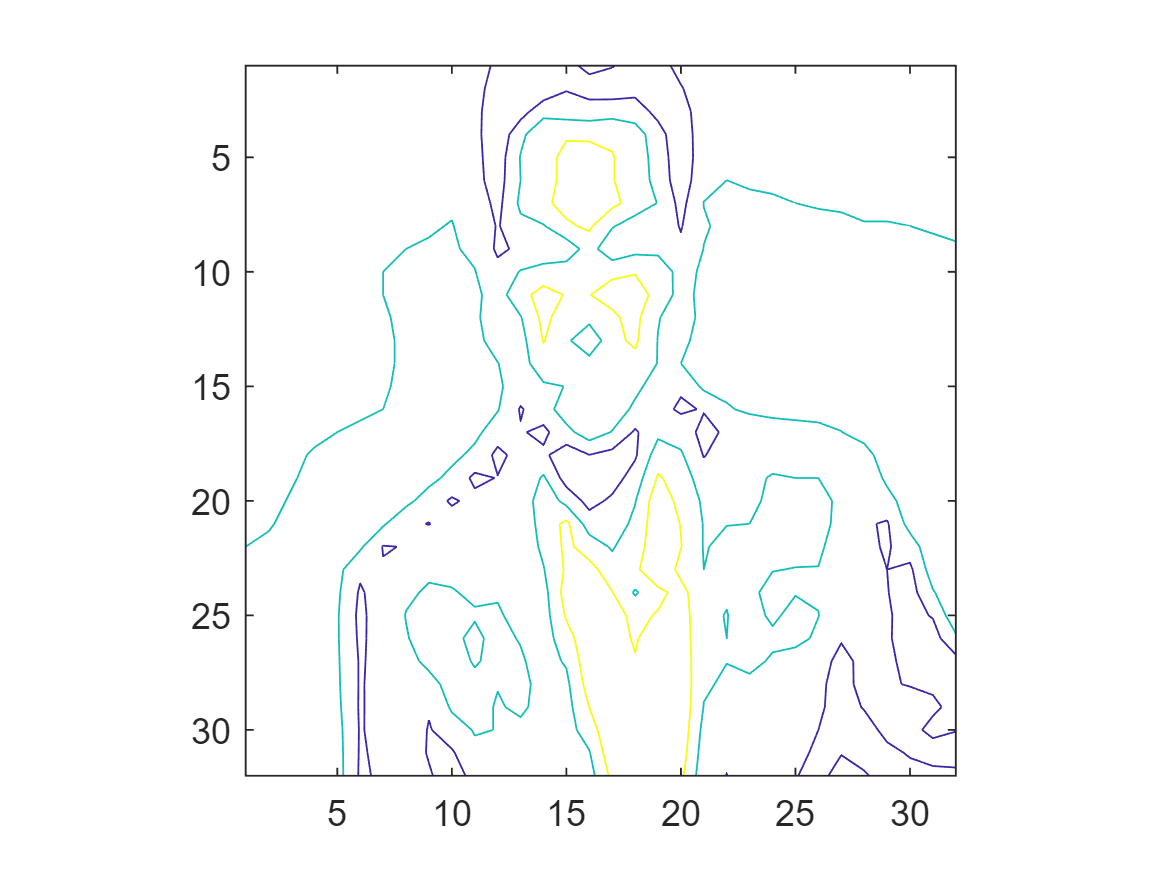

c =    71.0000   11.6939   11.4359   11.3095   11.2879   11.3469   11.4091   11.6786   11.9074   11.8305   12.0000   12.5000   12.0980   12.2000   12.3023   12.3368   12.5054   13.0000   13.3881   14.0000   15.0000   16.0000   17.0000   18.0000   18.6222   19.0000   19.3485   19.4557   19.5190   19.7532   19.9000   20.0000   20.0667   20.2375   20.4524   20.5309   20.5119   20.4337   20.1091   20.0000   19.5484   71.0000   17.1304   17.0000   16.0000   15.5172   71.0000   32.0000   31.3333   31.0000
   40.0000    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000    9.3704    9.0000    8.0000    7.0000    6.0000    5.0000    4.0000    3.3611    3.0000    2.5176    2.1176    2.4792    2.4706    2.3913    3.0000    3.4250    4.0000    5.0000    6.0000    7.0000    8.0000    8.2667    8.0000    7.0000    6.0000    5.0000    4.0000    3.0000    2.0000    1.8235    1.0000    4.0000    1.0000    1.0857    1.3784    1.0000   20.0000   26.7164   26.0000   25

c=imcontour(I,3)

B = c(:,1)

B =     71
    40


B=c

B =    71.0000   11.6939   11.4359   11.3095   11.2879   11.3469   11.4091   11.6786   11.9074   11.8305   12.0000   12.5000   12.0980   12.2000   12.3023   12.3368   12.5054   13.0000   13.3881   14.0000   15.0000   16.0000   17.0000   18.0000   18.6222   19.0000   19.3485   19.4557   19.5190   19.7532   19.9000   20.0000   20.0667   20.2375   20.4524   20.5309   20.5119   20.4337   20.1091   20.0000   19.5484   71.0000   17.1304   17.0000   16.0000   15.5172   71.0000   32.0000   31.3333   31.0000
   40.0000    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000    9.3704    9.0000    8.0000    7.0000    6.0000    5.0000    4.0000    3.3611    3.0000    2.5176    2.1176    2.4792    2.4706    2.3913    3.0000    3.4250    4.0000    5.0000    6.0000    7.0000    8.0000    8.2667    8.0000    7.0000    6.0000    5.0000    4.0000    3.0000    2.0000    1.8235    1.0000    4.0000    1.0000    1.0857    1.3784    1.0000   20.0000   26.7164   26.0000   25

path = [ 0.1*B; zeros(1,numcols(B))];
k = find(isnan(path(1,:)));
path(:,k) = path(:,k-1); path(3,k) = 0.2

path =     7.1000    1.1694    1.1436    1.1310    1.1288    1.1347    1.1409    1.1679    1.1907    1.1831    1.2000    1.2500    1.2098    1.2200    1.2302    1.2337    1.2505    1.3000    1.3388    1.4000    1.5000    1.6000    1.7000    1.8000    1.8622    1.9000    1.9348    1.9456    1.9519    1.9753    1.9900    2.0000    2.0067    2.0238    2.0452    2.0531    2.0512    2.0434    2.0109    2.0000    1.9548    7.1000    1.7130    1.7000    1.6000    1.5517    7.1000    3.2000    3.1333    3.1000
    4.0000    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    0.9370    0.9000    0.8000    0.7000    0.6000    0.5000    0.4000    0.3361    0.3000    0.2518    0.2118    0.2479    0.2471    0.2391    0.3000    0.3425    0.4000    0.5000    0.6000    0.7000    0.8000    0.8267    0.8000    0.7000    0.6000    0.5000    0.4000    0.3000    0.2000    0.1824    0.1000    0.4000    0.1000    0.1086    0.1378    0.1000    2.0000    2.6716    2.6000  

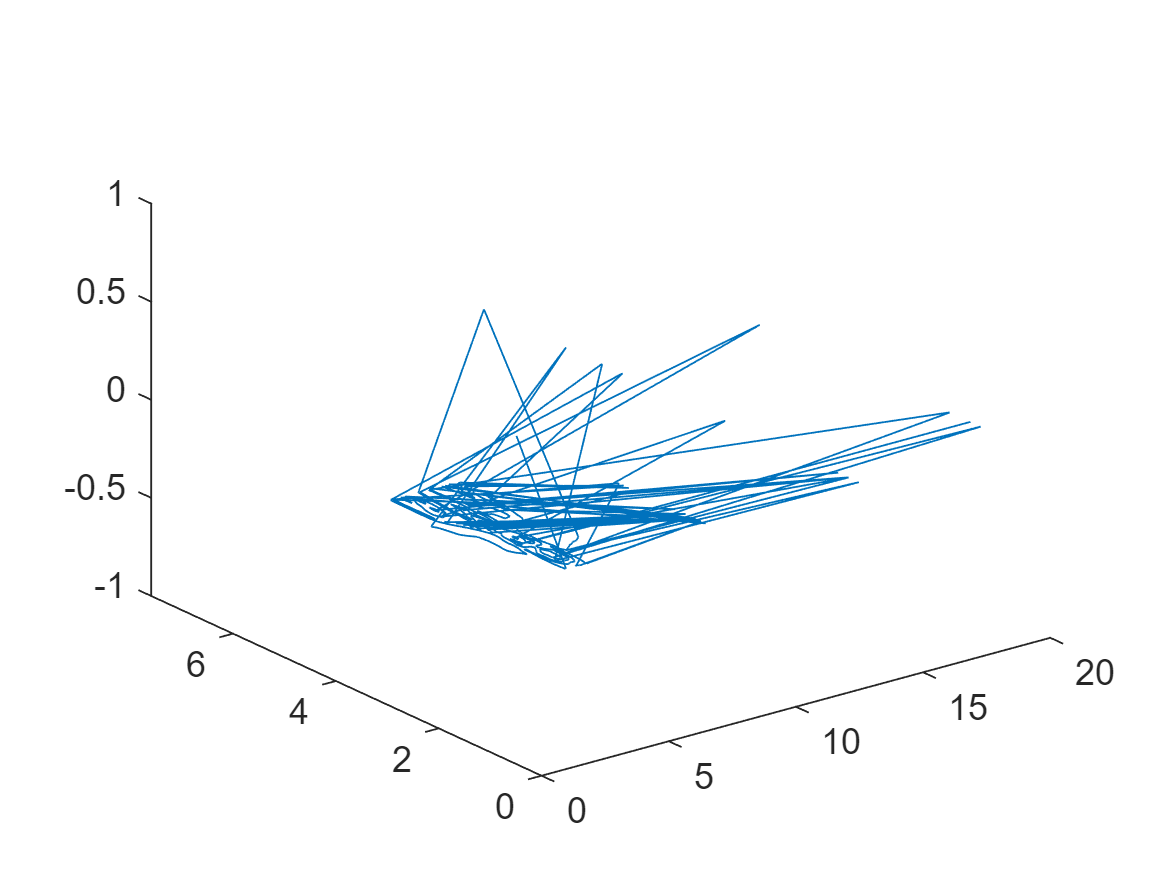

traj = mstraj(path(:,2:end)', [0.5 0.5 0.5], [], path(:,1)',	0.02, 0.2);
plot3(traj(:,1), traj(:,2), traj(:,3))

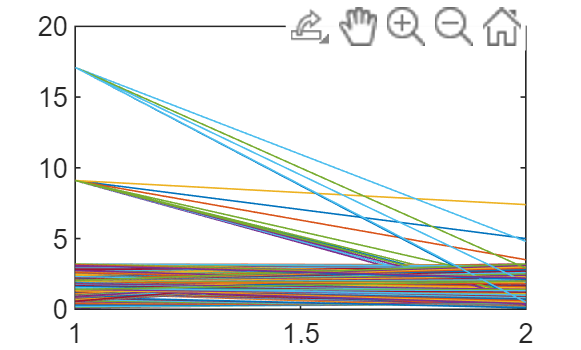

plot(B*0.1)